## 1. Cинтез системы с использованием "метода переоборудования"

####             a) Передаточная функция системы

load("data.mat")



syms ia ua w e M
syms R L J Ce
syms dia dw

eq(1) = L*dia + R*ia == ua-e;
eq(2) = J*dw==M;
eq(3) = e == Ce*w;
eq(4) = M ==Ce*ia;
S1=solve(eq, [dia dw e M]);
disp(collect(S1.dia, [ia w ua]));

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,w+\frac{\mathrm{ua}}{L}$$

disp(collect(S1.dw, [ia w ua]));

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A= [-R/L -Ce/L; 
    Ce/J 0];
B = [1/L; 0];
C = [0 1];
D = [0];
syms s
Wwa = C*(s*eye(2) - A)^-1*B + D ;
disp(collect(Wwa, s)) 

$$\frac{\mathrm{Ce}}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

syms T1 T2 Kob
Wsmp = Kob/(T1*s +1)/(T2*s+1);
disp(collect(expand(Wsmp),s))

$$\frac{\mathrm{Kob}}{\left(T_{1}\,T_{2}\right)\,s^{2}+\left(T_{1}+T_{2}\right)\,s+1}$$

eqn(1) = T1*T2 == J*L/Ce^2;
eqn(2) = T1+T2 == J*R/Ce^2;
s2 = solve(eqn,[T1 T2]);
s2.T1

$$ans = \left(\begin{array}{c} \frac{J\,R}{{\mathrm{Ce}}^{2}}-\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}}+\frac{J\,R}{{\mathrm{Ce}}^{2}} \end{array}\right)$$

s2.T2

$$ans = \left(\begin{array}{c} \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ -\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}} \end{array}\right)$$

ob.T1 = -(sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) - ob.J*ob.R)/(2*ob.Ce^2);
ob.T2 = (sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) + ob.J*ob.R)/(2*ob.Ce^2);
disp(ob.T1)

    0.0028



disp(ob.T2)

  231.9203



ob.kdw = 180/pi;
ob.Kob = ob.kdw/ob.Ce;

#### б) Расчёт регулятора скорости

syms Tu
T1 = Tu;
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = (4*Tu*s+1)/(8*Tu^2*s^2*(Tu*s+1));
Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{2}\,s+1\right)\,\left(4\,\mathrm{Tu}\,s+1\right)}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}\,s^{2}}$$

$$Wreg0 = \frac{\frac{1}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}}+\frac{s}{2\,\mathrm{Kob}\,\mathrm{Tu}}+\frac{T_{2}\,s}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}}+\frac{T_{2}\,s^{2}}{2\,\mathrm{Kob}\,\mathrm{Tu}}}{s^{2}}$$

$$\frac{\left(T_{2}\,s+1\right)\,\left(4\,\mathrm{Tu}\,s+1\right)}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}\,s^{2}}$$

в) Моделирование работы системы настроенной на технический оптимум

T0 = 0.1*Tu;

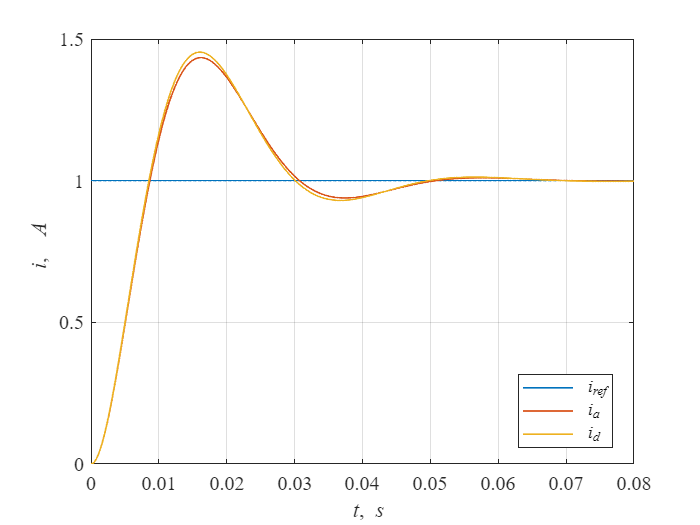

Tmdl = 0.08;
spl.Tu = ob.T1;
To = 0.1 *spl.Tu;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);

warning off
b = sim('Lab52p1b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.9*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 14.7*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.4564

fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 45.6%


T0 = 1*Tu

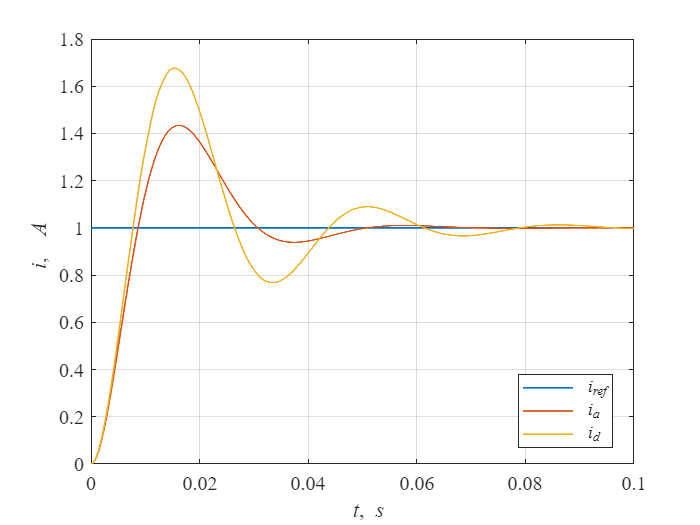

Tmdl = 0.1;
spl.Tu = ob.T1;
To = 1 *spl.Tu;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);

warning off
b = sim('Lab52p1b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.6*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 20.4*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.6828

fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 68.3%


## 2. Cинтез системы из условия получения в ней стандартной настройки на "оптимум по модулю" с использованием эквивалентной непрерывной системы.

####         а) Апроксимация апереодическим звеном

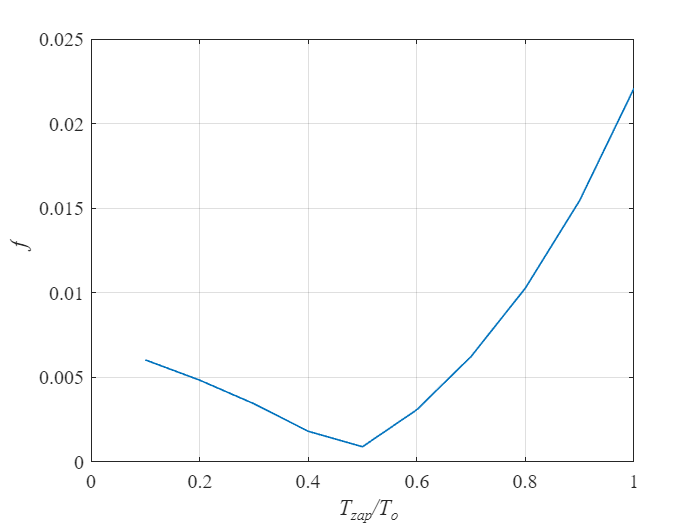

Tmdl = 0.2;
for i=1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab52p2','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

г) Синтез цифрового ПИ-регулятора методом переоборудования

T0 = 1 *T1

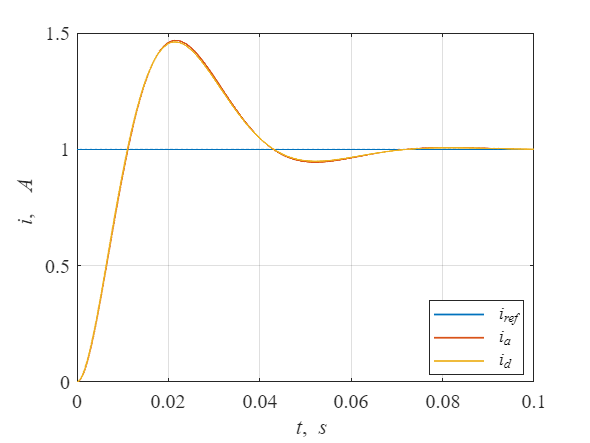

Tmdl = 0.1;
To = 1 *ob.T1;

spl.Tz = 0.5*To;
spl.Tu = ob.T1 + spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);


warning off
b = sim('Lab52p2','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.5*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 12.9*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.4611

fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 46.1%


T0 = 2 *T1

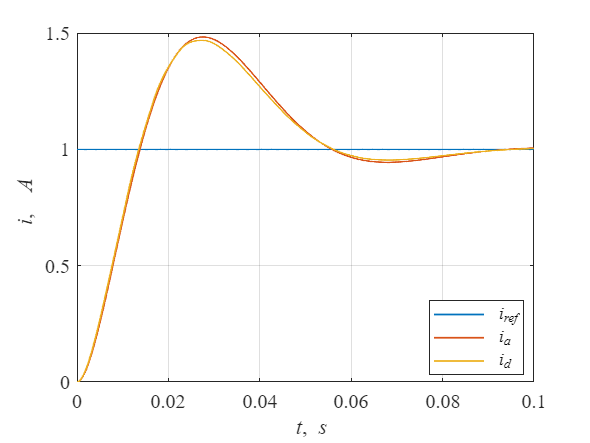

Tmdl = 0.1;
To = 2 *ob.T1;

spl.Tz = 0.5*To;
spl.Tu = ob.T1 + spl.Tz;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);


warning off
b = sim('Lab52p2','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.3*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 9.2*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.4636

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 46.4%


## **3. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ****>> Т****0****,**  **Т****2 ****>> Т****0 ****, ε = 0.**

#### **        a) Синтез регулятора скорости**

syms Tu T1
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = (4*Tu*s+1)/(8*Tu^2*s^2*(Tu*s+1));
Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)\,\left(4\,\mathrm{Tu}\,s+1\right)}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}\,s^{2}\,\left(\mathrm{Tu}\,s+1\right)}$$

####         б) моделирование работы системы     настроенной на "технический оптимум"

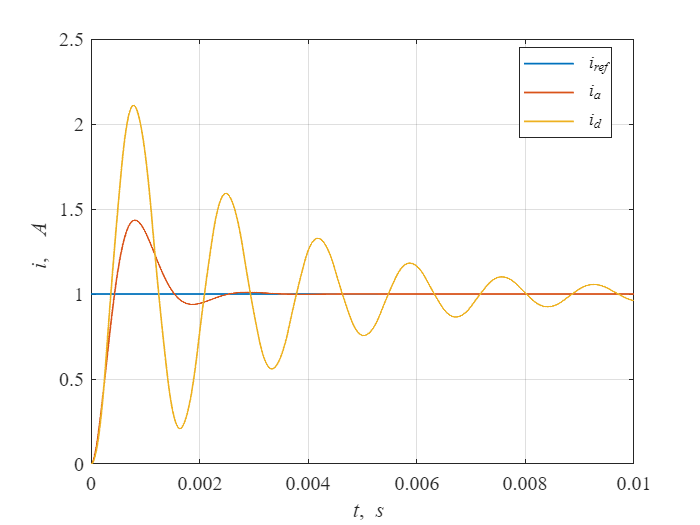

Tmdl = 0.01;

To = 0.1 *ob.T1;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;




spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab52p3','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.5*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 68.8*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 1.1942

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 119.4%


#### в)апроксимация

Tmdl = 0.1;
for i=1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab52p3b','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 

No system or file called 'Lab52p3b' found.

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Синтез цифрового ПД ПИ регулятора скорости методом переоборудования.

T0 = 0.2*T1

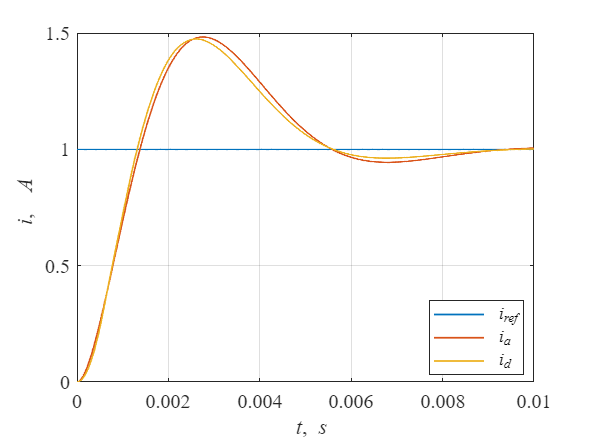

Tmdl = 0.01;

To = 0.2 *ob.T1;
spl.Tz = 0.5*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur + spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab52p3b','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.2*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 9.1*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.4723

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 47.2%


## **Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ****>> Т****0****,**  **Т****2 ****>> Т****0 ****, ε = *****Т******0*****.**

**Тоже самое, что и в прошлом пункте, только с запаздывание на один такт**

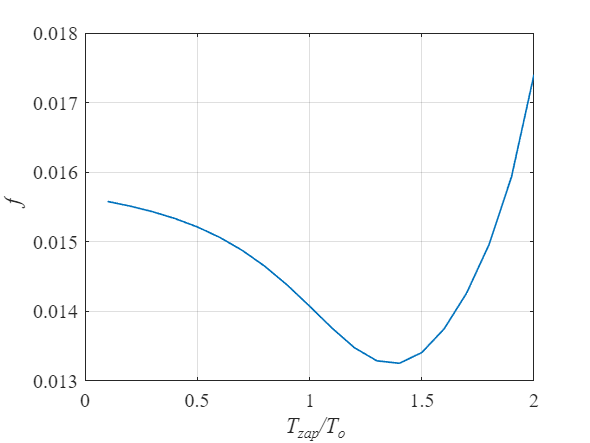

Tmdl = 0.05;
for i=1:20
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('Lab52p4','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Синтез цифрового ПД ПИ регулятора скорости методом переоборудования.

T0 = 0.1*T1

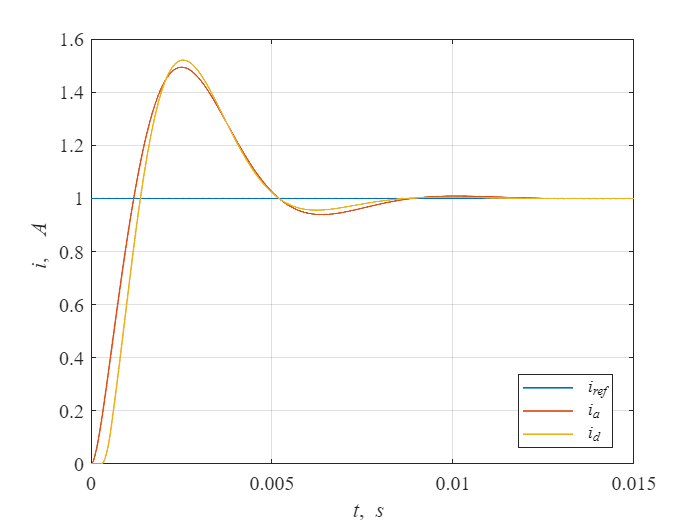

Tmdl = 0.015;

To = 0.2 *ob.T1;
spl.Tz = 1.4*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur + spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;




spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('Lab52p4','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'LineWidth', 1)
plot(t,wd,'LineWidth', 1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm, \it A')
legend ('\it i_{ref}', '\it i_a','\it i_d', 'location', 'best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.5*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 9.0*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.5207

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 52.1%
